# Estimating thust based on Throttle and rpm

As i couldn't find any official documentation from HQ Prop, i will need to rely on messured static thrust of a similar propeller.

Used data:

[https://database.tytorobotics.com/tests/qjm/dys-samguk-shu-hq-5040](https://database.tytorobotics.com/tests/qjm/dys-samguk-shu-hq-5040)

propData = readtable("Data\DYS Samguk Shu HQ 5040 - Rob Hessler.csv", VariableNamingRule="modify");

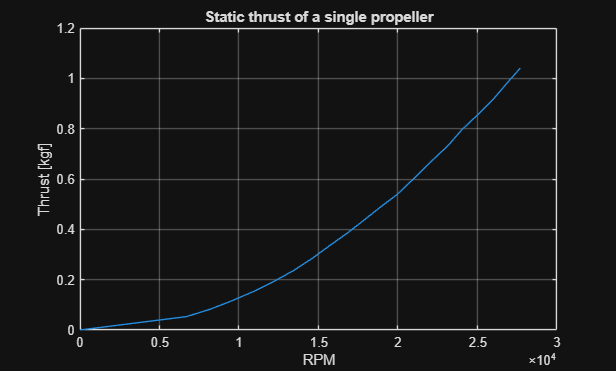

thrust =flip(propData.Thrust_kgf_);
rpm = flip(propData.RotationSpeed_rpm_);

figure;
plot(rpm, thrust);
grid on
xlabel("RPM")
ylabel("Thrust [kgf]")
title("Static thrust of a single propeller")

ex_range = 40000;
poly = 3;

[thrust_poly, S, mu] = polyfit(rpm, thrust, poly);
val = polyval(thrust_poly, rpm, S,  mu);

err = sum((val - thrust).^2)

err = 1.5402e-04

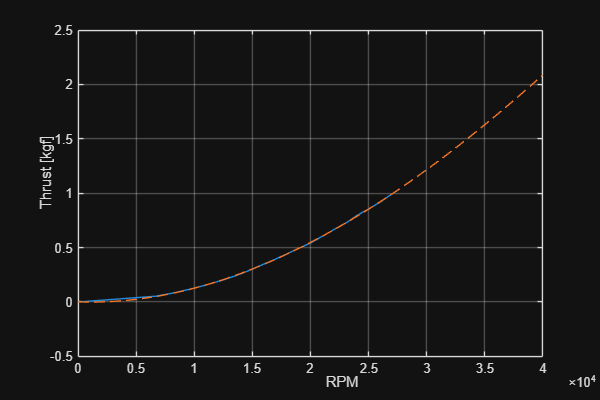


range = 0:100:ex_range;
thrust_pred = polyval(thrust_poly, range, S,  mu);

figure(Position=[0 0 600 400]);
plot(rpm, thrust, range, thrust_pred, "--");
grid on
xlabel("RPM")
ylabel("Thrust [kgf]")
title(sprintf("Aproximated thrust as %d-order polynomial", poly))

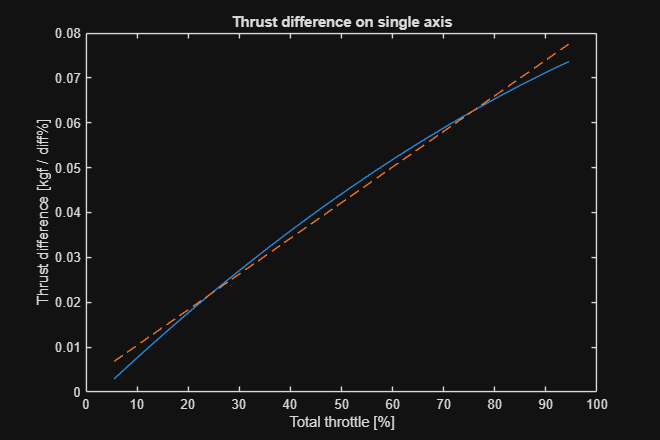

offset = 11; % [%]
refVoltage = 20; % [V]
refKV = 2000;      % [rpm * V]
throttle = linspace(0 + (offset / 200), 1 - (offset / 200), 2048);

% Assuming rpm is directly proportional to input voltage, actual rpm is going to be noticeably lower.
rpm_low = (throttle - (offset / 200)) * refVoltage * refKV;
rpm_high = (throttle + (offset / 200)) * refVoltage * refKV;

diff = (polyval(thrust_poly, rpm_high, S,  mu) - polyval(thrust_poly, rpm_low, S,  mu)) / offset;

thrust_diff_poly = polyfit(throttle, 2 * diff, 1);

plot(throttle * 100, 2 * diff, throttle * 100, polyval(thrust_diff_poly, throttle), "--");
xlabel("Total throttle [%]")
ylabel("Thrust difference [kgf / diff%]")
title("Thrust difference on single axis")